**Modèle de turbulence** discrétisé sur la colonne prenant en compte la force Coriolis et la vitesse du vent    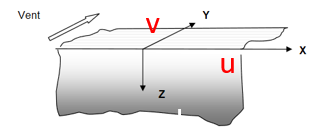

Equations de Navier Stockes :


$$\textrm{𝒇𝒖}=\frac{\textrm{𝝏}}{\textrm{𝝏z}}K\frac{\textrm{𝝏v}}{\textrm{𝝏z}}$$
                                                


$$-\textrm{𝒇v}=\frac{\textrm{𝝏}}{\textrm{𝝏z}}K\frac{\textrm{𝝏u}}{\textrm{𝝏z}}$$


Avec u et v les vitesses, K la turbulence et f la force de Coriolis

function [K,dK]=Turbulence2(L,N,W_vent,Lat,rhoW)

L correspond à la longueur totale de la colonne, N le nombre de mailles , W_vent la vitesse du vent en km/h,Lat la latitude , rhoW la densité de l'eau sur la profondeur de la colonne

**Discretisation de la colonne d'eau :**

dz = L/N; 
z=0:dz:L; 
z_=(z(1:end-1)+z(2:end))/2; 

dz correspon à la taille des mailles (constante), z_ au coordonnées selon z des centres des mailles et z aux coordonnées des extrémités des mailles

**Constantes :**

kappa=0.4;
Kmol=10^(-6);
rho_air=1.292 ;

Kappa la constante de Karman, Kmol la viscosité moléculaire (m2/S) et rho_air la densité de l'air

**Force de Coriolis **


$$\textrm{𝑓}=2\Omega \textrm{𝑠𝑖𝑛𝜙}$$


$\textrm{𝜙}$ la latitude et $\Omega$ la vitesse angulaire de la terre (valeur prise sur Wikipédia)

omega_T=7.2921*10^(-5);
f=2*omega_T*sin(Lat);

**Coefficient de Trainée (surface)**

z0=0.0002;   
Cd=(kappa/log(10/z0))^2;   

z0 la longueur de rugosité sur la surface de la mer (valeur wikipédia) et Cd le coefficient de trainée en considérant qu'il est mesuré à 10 m d'altitude. (Wikipédia)

**Vitesse en mêtre par seconde **

W=W_vent/3.6;

**Déclaration des inconnues u, v et K sur la colonne **

syms u [1,N+1]
syms v [1, N+1]
syms K  [1,N]

Les vitesses seront estimées sur les extrémités des mailles et la viscosité turbulente K au milieu des mailles :

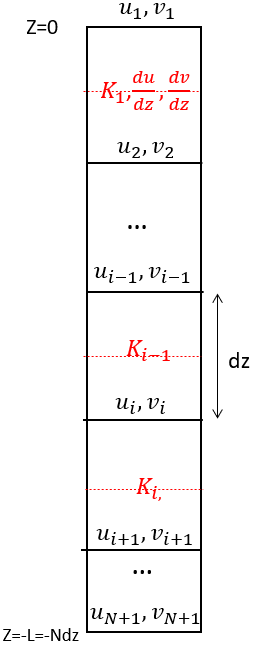

**Initialisation de la turbulence :**

L'expression de la viscosité turbulente en fonction de la profondeur est :


$$K\left(z\right)=K_{\textrm{mol}\;} +{\left(\kappa \;z\left(1-\frac{z}{L}\right)\right)}^2 \sqrt{\;{\left(\frac{\textrm{du}}{\textrm{dz}}\right)}^2 +{\left(\frac{\textrm{dv}}{\textrm{dz}}\right)}^2 }\;\;$$


Soit en z=-dz (au milieu de la première maille) :

init_K=K(1)==Kmol+((kappa*z_(1)*(1-z_(1)/L))^2)*sqrt(((u(2)-u(1))/dz)^2+((v(2)-v(1))/dz)^2);

**Conditions aux limites **

**Surface : **Continueté de la tension exercé sur la mer de part et d’autre de la surface de la mer. En z=0 (à la surface), on a l’égalité entre la tension de cisaillement exercé par le vent sur la mer et la tension du à la turbulence dans la mer** :**


$${\textrm{𝝉}}_{\textrm{vent}} ={\textrm{𝝉}}_{\textrm{turb}\;x\;\textrm{et}\;\textrm{turb}\;y}$$


${\textrm{𝜏}}_{\textrm{turb},x} ={\textrm{𝜌}}_w \textrm{𝐾}\frac{\textrm{du}}{\textrm{dz}}\;\;\;\;\;\;\;{\textrm{𝜏}}_{\textrm{turb},y} ={\textrm{𝜌}}_w \textrm{𝐾}\frac{\textrm{dv}}{\textrm{dz}}\;\;$et $\tau_{\textrm{vent}} =C_{d\;} \rho_{a\;} W|W|$

D'où :${\textrm{𝜌}}_w \textrm{𝐾}\frac{\textrm{du}}{\textrm{dz}}|_{z=0\;} ={\textrm{𝜌}}_w \textrm{𝐾}\frac{\textrm{dv}}{\textrm{dz}}|_{z=0\;} C_{d\;} \rho_{a\;} W^2$

En discrétisant, on obtient ces expressions

condition_surface1=K(1)*(u(2)-u(1))/dz==rho_air*Cd*W^2/rhoW;
condition_surface2= K(1)*(v(2)-v(1))/dz==rho_air*Cd*W^2/rhoW;  

**Fond : **Les vitesses u et v au fond de la colonne sont nulles car le fond de la colonne est imobile 


$$u|_{z=L} =v|_{z=L} =0$$


condition_fond1=u(N+1)==0;
condition_fond2=v(N+1)==0;

Tableau regroupant les conditions aux limites et initialisation :

equation=[condition_surface1,condition_surface2,init_K,condition_fond1,condition_fond2];

**Equations du système discrétisées le long de la colonne :**

Equations de Navier-Stockes discrétisées :


$${\textrm{fu}}_i =K_{i\;} \frac{\left(v_{i+1} -v_i \right)}{{\textrm{dz}}^2 }-K_{i-1} \frac{\left(v_i -v_{i-1} \right)}{{\textrm{dz}}^2 }$$



$${-\textrm{fv}}_i =K_i \frac{\left(u_{i+1} -u_i \right)}{{\textrm{dz}}^2 }-K_{i-1} \frac{\left(u_i -u_{i-1} \right)}{{\textrm{dz}}^2 }$$


Equations de turbulence :


$$K_i =K_{\mathrm{mol}\;} +{\left(\kappa \;z_i \left(1-\frac{z_i }{L}\right)\right)}^2 \sqrt{\;{\left(\frac{u_{i+1} -u_i }{\mathrm{dz}}\right)}^2 +{\left(\frac{v_{i+1} -v_i }{\mathrm{dz}}\right)}^2 }\;\;$$


for i=2:N
eqn1=f*u(i)==( K(i)*(v(i+1)-v(i))/dz^2)-(K(i-1)*(v(i)-v(i-1))/dz^2);
eqn2=-f*v(i)==(K(i)*(u(i+1)-u(i))/dz^2)-(K(i-1)*(u(i)-u(i-1))/dz^2);
eqn3=  K(i)==Kmol+(kappa*z_(i)*(1-z_(i)/L))^2*sqrt(((u(i+1)-u(i))/dz)^2+((v(i+1)-v(i))/dz)^2);

equation=[equation,eqn1,eqn2,eqn3];

end

**Résolution du système **

Resolution=vpasolve(equation,[K,v,u]);
Result=structfun(@double,Resolution);

**Calcul de K et dK**

K=interp1(-z_,Result(1:N),z,'pchip');
dK=diff(K);
plot(K,-z)
hold on 
xlabel('Viscosité turbulente (m^2/s')
ylabel('profondeur(m)')
end